%used to find the social interaction time during experimentation


%video name/ CHANGE EVERYTIME
a=readtable('File name');

%frames of the video
frames=a{:,1};
 
%coordinates and likelihood of all dots
xn=a{:,2};              %Head
yn=a{:,3};              
likenose=a{:,4};       
 
xc1=a{:,5};             %one
yc1=a{:,6};            
likec1=a{:,7};
 
xc2=a{:,8};             %two
yc2=a{:,9};
likec2=a{:,10};
 
xc3=a{:,11};            %three
yc3=a{:,12};
likec3=a{:,13};
 
xc4=a{:,14};            %four
yc4=a{:,15};
likec4=a{:,16};
 
xc5=a{:,17};            %five
yc5=a{:,18};
likec5=a{:,19};
 
xc6=a{:,20};            %six
yc6=a{:,21};
likec6=a{:,22};
 
xc7=a{:,23};            %seven
yc7=a{:,24};
likec7=a{:,25};
 
xtail=a{:,26};            %tail
ytail=a{:,27};
liketail=a{:,28};



%distances from head to circle
dnc1nose=sqrt((xn-xc1).^2 + (yn-yc1).^2);
dnc2nose=sqrt((xn-xc2).^2 + (yn-yc2).^2);
dnc3nose=sqrt((xn-xc3).^2 + (yn-yc3).^2);
dnc4nose=sqrt((xn-xc4).^2 + (yn-yc4).^2);
dnc5nose=sqrt((xn-xc5).^2 + (yn-yc5).^2);
dnc6nose=sqrt((xn-xc6).^2 + (yn-yc6).^2);
dnc7nose=sqrt((xn-xc7).^2 + (yn-yc7).^2);

 
distancenose=[dnc1nose dnc2nose dnc3nose dnc4nose dnc5nose dnc6nose dnc7nose];
 
%distance from tail to circle
dnc1tail=sqrt((xtail-xc1).^2 + (ytail-yc1).^2);
dnc2tail=sqrt((xtail-xc2).^2 + (ytail-yc2).^2);
dnc3tail=sqrt((xtail-xc3).^2 + (ytail-yc3).^2);
dnc4tail=sqrt((xtail-xc4).^2 + (ytail-yc4).^2);
dnc5tail=sqrt((xtail-xc5).^2 + (ytail-yc5).^2);
dnc6tail=sqrt((xtail-xc6).^2 + (ytail-yc6).^2);
dnc7tail=sqrt((xtail-xc7).^2 + (ytail-yc7).^2);

 
distancetail=[dnc1tail dnc2tail dnc3tail dnc4tail dnc5tail dnc6tail dnc7tail];
 
%minimum distance that is found between nose and a circle and plot


Mnose=min(distancenose,[],2);
%plot(frames,Mnose);
 
%minimum distance that is found between tail and a circle and plot

Mtail=min(distancetail,[],2);
%plot(frames,Mtail);
 
 
%removal of values we do not want while still keeping the original index

compact= [frames Mnose likenose];
compact1= [frames Mnose likenose];
compact2= [frames Mtail liketail];
 
%Circle likelihoods all in one thing
circlelike= [frames likec1 likec2 likec3 likec4 likec5 likec6 likec7];
 
%if nose distance is greater than tail distance make the distance zero


for i=1:frames
   if compact1(i,2)>compact2(i,2)
       compact1(i,2)=0;
   end
   if circlelike(:,2)<0.1
       compact1(i,2)=0;
   end
   if circlelike(:,3)<0.1
       compact1(i,2)=0;
   end
   if circlelike(:,4)<0.1
       compact1(i,2)=0;
   end
   if circlelike(:,5)<0.1
       compact1(i,2)=0;
   end
   if circlelike(:,6)<0.1
       compact1(i,2)=0;
   end
   if circlelike(:,7)<0.1
       compact1(i,2)=0;
   end
   if compact2(:,3)<0.1
       compact1(i,2)=0;
   end
end



 
%removing labels that have low possibility of being there

Findnose=compact1(:,3)<0.10; %find all cases where the nose likelihood is less than 0.1
                            

compact1(Findnose,:)=[]; %make all values in a row zero when the nose likelihood is less than 0.1
                        
%bar(compact(:,1),compact(:,2)); %plot of frames verses the minimum distance between nose and circle
 
 
%Findtail=compact2(:,3)<0.10; %find all cases where the tail likelihood is less than 0.1


%compact(Findtail,:)=[]; %make all values in a row zero when the tail likelihood is less than 0.1


%bar(compact2(:,1),compact2(:,2)); %plot of frames verses the minimum distance between tail and circle

 
FindThreshnose=compact1(:,2)>50; %find values where the distance is greater than the value
                                  

compact1(FindThreshnose,:)=[]; %make zero all rows where the value is greater than the value
                               

%bar(compact(:,1),compact(:,2)); %plot of frames verses minimum distance between nose and circle

 
 
takeawayzero=compact1(:,2)== 0;
compact1(takeawayzero,:)=[];
%bar(compact(:,1),compact(:,2));
 
%turning remaining frames into a time in order to determine amount of social time.
timeoftotalvidsec=302%NEEDS TO BE CHANGED EVERYTIME

timeoftotalvidsec = 302

                       
interactStartSec=0 %NEEDS TO BE CHNAGED EVERYTIME

interactStartSec = 0

                       
framespersec= length(frames)/timeoftotalvidsec

framespersec = 60.1391

socialtime=length(compact1)/framespersec

socialtime = 110.2445

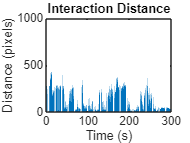


timetosec= (compact(:,1)/framespersec); %Interaction Distance
beforeInteraction=timetosec < interactStartSec; %find values where the distance is greater than the value
compact(beforeInteraction,:)=[];
timetosec(beforeInteraction) = [];

timetosec1= (compact1(:,1)/framespersec); %Interacting Time
beforeInteraction=timetosec1 < interactStartSec; %find values where the distance is greater than the value
compact1(beforeInteraction,:)=[];
timetosec1(beforeInteraction) = [];

figure(1);
bar(timetosec, compact(:,2));   %Interaction distance
title("Interaction Distance")
xlabel("Time (s)")
ylabel("Distance (pixels)")

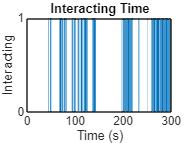


figure(2);  %interacting Time update
y=[(timetosec1*0+1)]; %Code to sync Y values
bar(timetosec1, y)
xlim([0, timeoftotalvidsec])
yticks ([0,1])%ylim([0, 1])
title("Interacting Time")
xlabel("Time (s)")
ylabel("Interacting")



fig = figure(3);
times = compact1(:,1);
prev = times(1);
bars = [];
prevBlock = 0;
counter = 0;
for idx = 2:length(times)
    val = times(idx);
    if val - prev <= 1
        counter = counter+1;
        prev = val;
        prevBlock = 0;
    else
       if counter > 0
          bars = [bars counter/framespersec];
        end
        if prevBlock == 0
            bars = [bars (val-prev)/framespersec];
            prevBlock = 1;
        else
            bars = [bars 1/framespersec (val-prev)/framespersec];
        end
        
        prev = val;
        counter = 0;
    end
    end
%bars = [interactStartSec bars];


timeStamps = zeros(1,length(bars));
curTime = bars(1);
for idx = 2:length(bars)
   timeStamps(idx-1) = curTime;
    curTime = curTime + bars(idx);
end

stampsAndInteractions = [timeStamps' interactions']

stampsAndInteractions =     0.2328         0
    0.2494    1.0000
    2.7769         0
    4.4896    1.0000
    4.5395         0
    5.1215    1.0000
    6.6014         0
    8.0979    1.0000
    9.6609         0
   10.1432    1.0000


writematrix(stampsAndInteractions,'interactions.csv') 

Results=[timetosec compact(:,2)];



 
